# Sample script of LETLAYER

 Copyright (c) Shogo MURAMATSU, 2021

 All rights reserved.

type letLayer

classdef letLayer < nnet.layer.Layer
    % 
    % (21) in F. Luisier, T. Blu and M. Unser, "A New SURE Approach to Image Denoising: Interscale Orthonormal Wavelet Thresholding," in IEEE Transactions on Image Processing, vol. 16, no. 3, pp. 593-606, March 2007, doi: 10.1109/TIP.2007.891064.Example custom Soft-thresholding layer.
    %
    
    properties
        NumberOfChannels
        IsInterScale
    end
    
    properties(Learnable)
        % Layer learnable parameters
        Sigma
        a1
        a2
        b1
        b2
    end
    
    methods
        function layer = letLayer(varargin) 
            p = inputParser;
            addParameter(p,'Name','')
            addParameter(p,'Sigma',1)
            addParameter(p,'IsInterScale',true)
            addParameter(p,'NumberOfChannels',1)
            parse(p,varargin{:})
            
            % Set layer name.
            layer.Name = p.Results.Name;
            layer.IsInterScale = p.Results.IsInterScale;
            layer.

layer = letLayer('Name','let','Sigma',1e-1)

layer =   letLayer のプロパティ:

                Name: 'let'
           NumInputs: 2
          InputNames: {'child'  'parent'}
    NumberOfChannels: 1
        IsInterScale: 1

   学習可能パラメーター
               Sigma: 0.1000
                  a1: 1
                  a2: -1
                  b1: 1
                  b2: 0

  すべてのプロパティを表示


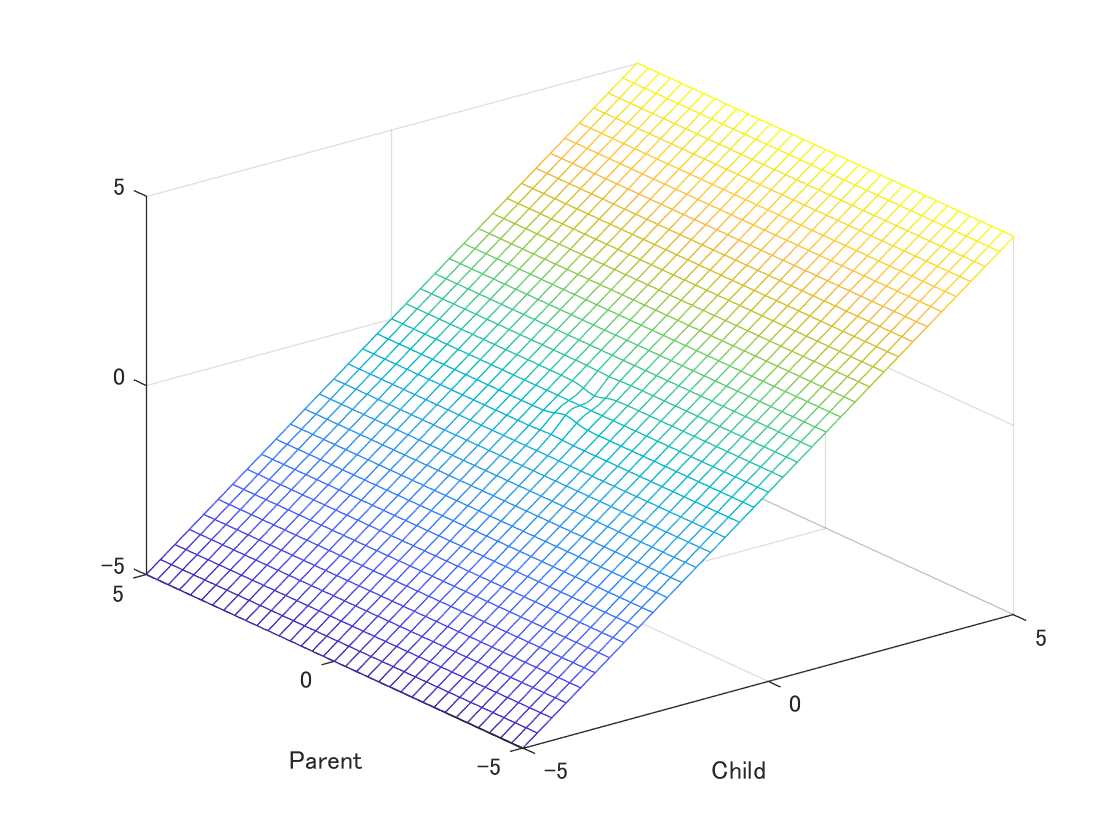



fmesh(@(x,y) extractdata(layer.predict(dlarray(x),dlarray(y))))
xlabel('Child')
ylabel('Parent')

checkLayer(layer,{[24 24 20],[12 12 20]},'ObservationDimension',4)

コード生成互換性テストをスキップします。コード生成用の層の有効性をチェックするには、'CheckCodegenCompatibility' および 'ObservationDimension' オプションを指定します。
 
nnet.checklayer.TestLayerWithoutBackward を実行しています
.......... .......
nnet.checklayer.TestLayerWithoutBackward が完了しました
__________

テストの概要:
	 17 パス、0 失敗、0 未完了、5 スキップ。
	 経過時間: 0.17162 秒。


layer = letLayer('Name','let','Sigma',1e-1,'IsInterScale',false)

layer =   letLayer のプロパティ:

                Name: 'let'
    NumberOfChannels: 1
        IsInterScale: 0

   学習可能パラメーター
               Sigma: 0.1000
                  a1: 1
                  a2: -1
                  b1: []
                  b2: []

  すべてのプロパティを表示


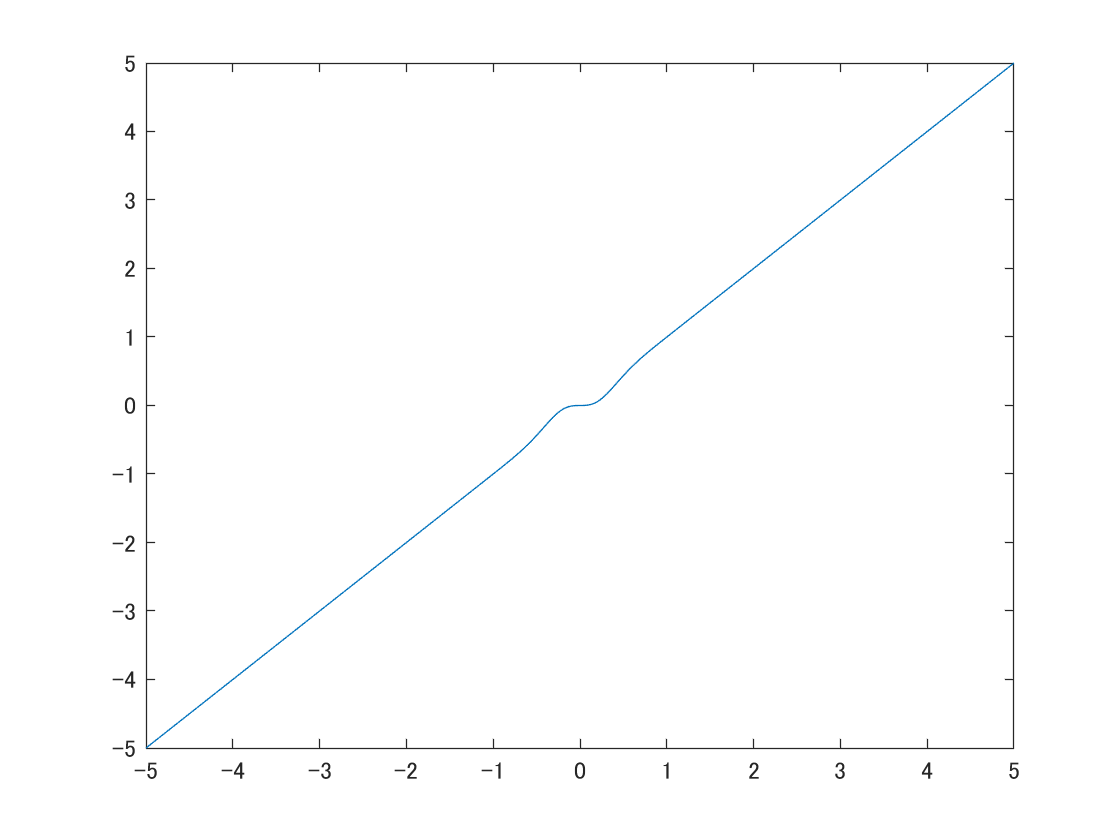

fplot(@(x) extractdata(layer.predict(dlarray(x))))

checkLayer(layer,[24 24 20],'ObservationDimension',4)

コード生成互換性テストをスキップします。コード生成用の層の有効性をチェックするには、'CheckCodegenCompatibility' および 'ObservationDimension' オプションを指定します。
 
nnet.checklayer.TestLayerWithoutBackward を実行しています
.......... .......
nnet.checklayer.TestLayerWithoutBackward が完了しました
__________

テストの概要:
	 17 パス、0 失敗、0 未完了、5 スキップ。
	 経過時間: 0.064939 秒。
